## Problem 1. 

Draw a line plot that shows the Gaussian probability distribution with mean 50 and standard deviation 10. Label the axes.

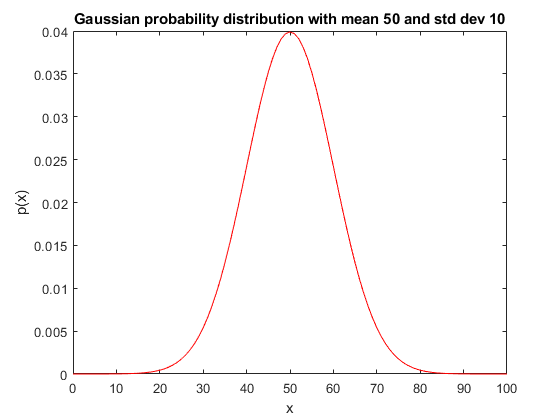

sigma = 10;     % standard deviation
mn = 50;        % mean
x = 0:100;      % x-values to evaluate function at

% The Gaussian function at all x-values
y = 1 / (sigma * sqrt(2 * pi)) * exp(-(x-mn).^2 / (2 * sigma^2));

% Visualize the results
figure;
plot(x,y,'r-');
xlabel('x');
ylabel('p(x)');
title(sprintf('Gaussian probability distribution with mean %d and std dev %d', mn, sigma));

## Problem 2. 

The `data1 `variable in Homework2.mat is a matrix of dimensions 3x20. Each row contains measurements obtained for a distinct group of subjects. We are interested in assessing whether there are any differences across the three groups. 

The metric that we will use is variability in the group means (i.e. compute the mean of each group and then compute the standard deviation across the three mean values). If this variability is high, that would suggest that the groups are different, whereas if the variability is low, that would suggest that the groups are the same. 

Use randomization to test the null hypothesis that all three groups come from the same underlying distribution. Run 10000 simulations and calculate a one-tailed *p*-value. Echo the computed *p*-value to the screen.

file = matfile('Homework2.mat');
data1 = file.data1;
simulationsCount = 10000;

means = mean(data1, 2);
shuffledStndDevs = zeros(1, simulationsCount);

% Calculate means for each of the groups
disp('Means:');

Means:


disp(means');

    0.2595   -0.1361    0.9165



% Calculate standard deviation of means
stndDev = std(means);
fprintf('Standard deviation: %f\n', stndDev);

Standard deviation: 0.531689


% Merge all the data
mergedData = data1(:);

% Randomly divide the given merged data set into 3 groups and calculate the standard deviation of means
% (repeat 10000 times);
for i = 1 : simulationsCount
    
    % Shuffle data in merged data and form new 3*20 random matrix
    shuffledData = mergedData(randperm(length(mergedData)));
    shuffledData1 = reshape(shuffledData, 3, 20);
    
    shuffledMeans = mean(shuffledData1, 2);
    
    % One-tailed test will operate with the values of standard deviation;
    shuffledStndDevs(i) = std(shuffledMeans); 
    
end

% The null hypothesis: all three groups come from the same underlying distribution;
% we accept that fact until the evidence indicates otherwise;

% result p-value will show what part of tests resulted with std' that is significantly
% greater than std value;
% sum() will return the count of element that are greater than stndDev
pValueOT = sum(shuffledStndDevs > stndDev) / simulationsCount;
fprintf('One-tailed p-value: %.5f\n', pValueOT);

One-tailed p-value: 0.01190


## Problem 3. 

Suppose we measure a group of 100 subjects before and after a certain manipulation. 

The `data2a `variable in Homework2.mat is a vector of dimensions 1 x 100 with the pre-manipulation measurement, and the `data2b `variable in Homework2.mat is a vector of dimensions 1 x 100 with the post-manipulation measurement. Quantify the manipulation effect by subtracting the pre-manipulation from the post-manipulation measurement. 

Then use bootstrapping to test the null hypothesis that the differences come from a probability distribution with mean 0. Run 10,000 simulations and calculate a two-tailed *p*-value. Echo the computed *p*-value to the screen.

% Initialize simulations count
simulationsCount = 10000;

% Pre-manipulation measurements
data2a = file.data2a;

% Post-manipulation measurements
data2b = file.data2b;

% Substract the pre-manipulation data from the post-manipulation measurement
diff = minus(data2b, data2a);

% Calculate the actual mean value
actualMean = mean(diff);
calcMeans = zeros(simulationsCount, 1);

% Substract from the diff values the mean of itself
substr = diff - mean(diff);

% The null hyp-s: the differences come from a distribution with mean = 0;
% that means that all the bootstrapped vectors will return approximately the same mean values;

% 10000 times: shuffle the dataset and calculate the mean
for i = 1 : simulationsCount
    ix = ceil(length(substr) * rand(length(substr), 1)); % Bootstrap
    calcMeans(i) = mean(substr(ix)); % Record the result
end

% Two-tailed p-value:
% Since we assume, that values come from a distribution with mean = 0,
% then to calculate two-tailed p-value we will count following values: 
% values(!=0) == values(>0) + values(<0)
pValueTT = sum(abs(calcMeans) > abs(actualMean)) / simulationsCount;

fprintf('Two-tailed p-value: %.5f\n', pValueTT);

Two-tailed p-value: 0.04170


## Problem 4. 

Flip a coin *n *times and count the number of heads obtained. Repeat this 10,000 times and visualize the distribution of results using a histogram. Perform this simulation for different *n *values (*n*= 10, 100, 1000) and show the resulting histograms on three different subplots of a single figure. For each subplot, label its axes and provide a title.

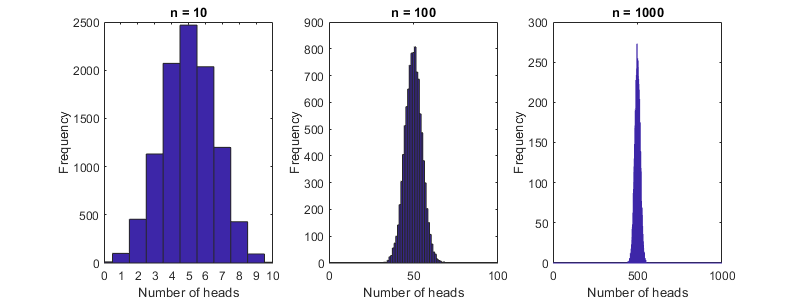

% Define number of coin flips
ns = [10 100 1000];

% Create a new figure and resize it
figure;
set(gcf,'Position',[100 100 800 300]);

% Loop over number of coin flips
for p=1:length(ns)
    
    % Perform 10000 simulations of random coin flips
    flips = round(rand(10000, ns(p)));
    
    % Count number of heads in each simulation
    dist = sum(flips == 0, 2);
    
    % Initalize subplot
    subplot(1,length(ns),p);
    
    % Plot histogram with bin centers at each possible number of heads
    hist(dist, 0:1:ns(p));
    
    % Make sure there are good axis bounds
    ax = axis;
    axis([0 ns(p) ax(3:4)]);
    
    % Label axes and give a title
    xlabel('Number of heads');
    ylabel('Frequency');
    title(sprintf('n = %d', ns(p)));
    
end